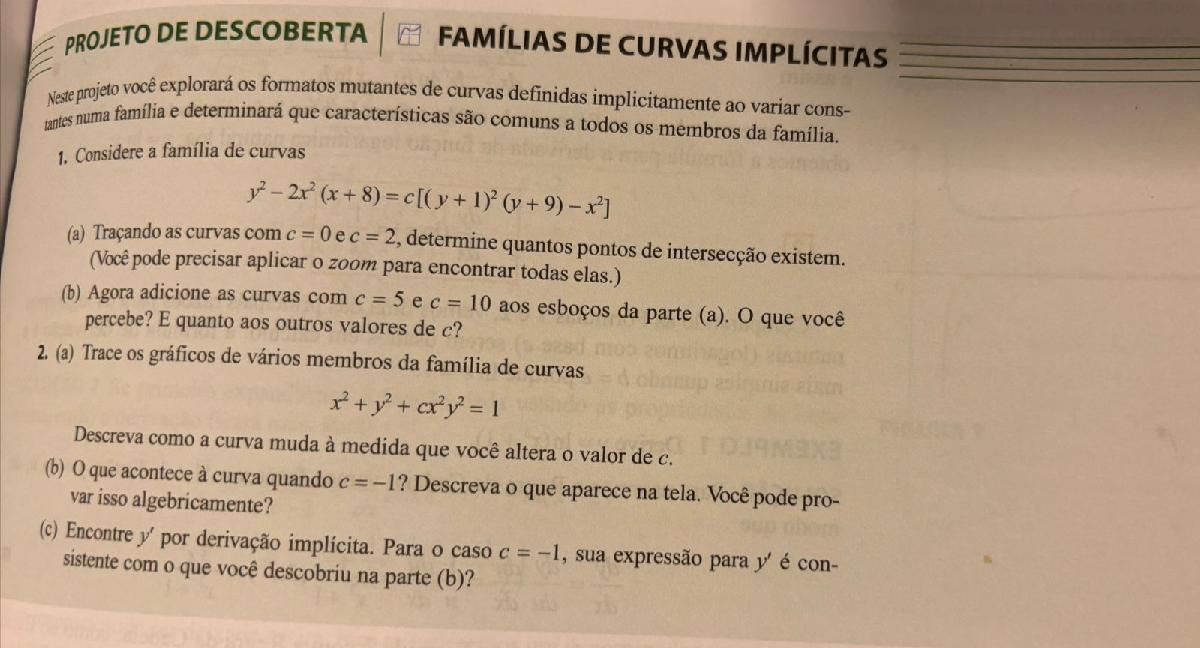

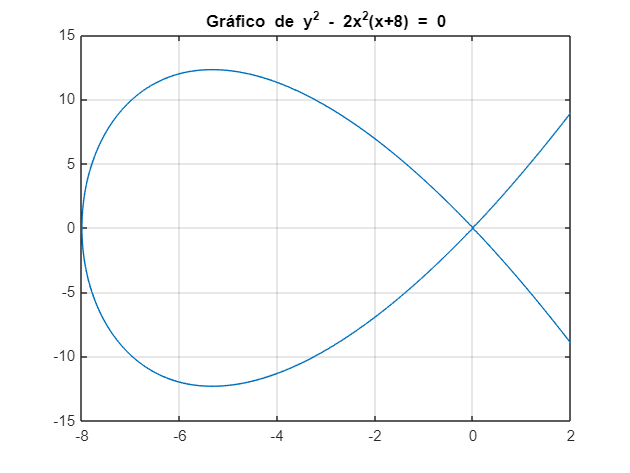

fimplicit(@(x,y) y.^2 - 2*x.^2.*(x+8), [-8, 2, -15, 15])
grid on
title(['Gráfico de y^2 - 2x^2' ...
    '(x+8) = 0'])

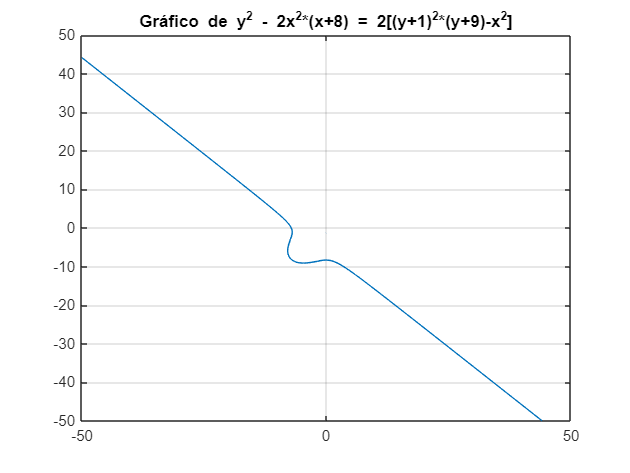

f = @(x,y) y.^2 - 2*x.^2.*(x+8) - 2*((y+1).^2.*(y+9)-x.^2);
fimplicit(f, [-50, 50, -50, 50])
grid on
title('Gráfico de y^2 - 2x^2*(x+8) = 2[(y+1)^2*(y+9)-x^2]')

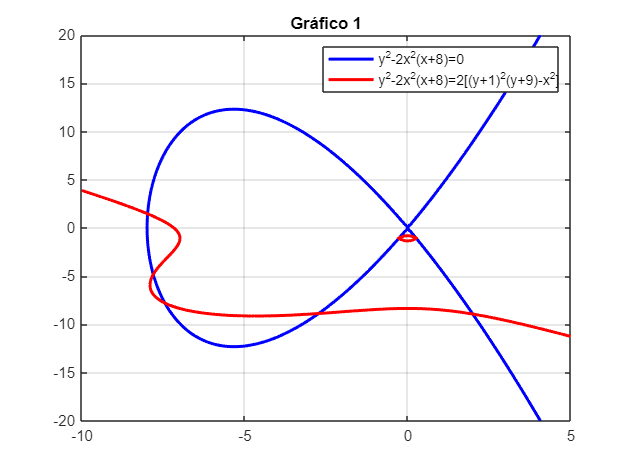

% Define as funções implícitas
f1 = @(x,y) y.^2 - 2*x.^2.*(x+8);
f2 = @(x,y) y.^2 - 2*x.^2.*(x+8) - 2*((y+1).^2.*(y+9)-x.^2);

% Cria uma nova figura
figure;

% Plota a primeira equação
fimplicit(f1, [-10, 5, -20, 20], 'b', 'LineWidth', 2)
hold on

% Plota a segunda equação
fimplicit(f2, [-10, 5, -20, 20], 'r', 'LineWidth', 2)

grid on
legend('y^2-2x^2(x+8)=0', 'y^2-2x^2(x+8)=2[(y+1)^2(y+9)-x^2]')
title('Gráfico 1')
hold off

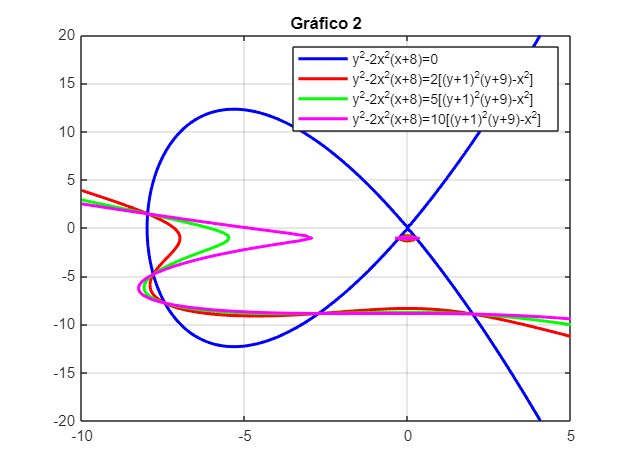

% Define as funções implícitas
f1 = @(x,y) y.^2 - 2*x.^2.*(x+8);
f2 = @(x,y) y.^2 - 2*x.^2.*(x+8) - 2*((y+1).^2.*(y+9)-x.^2);
f3 = @(x,y) y.^2 - 2*x.^2.*(x+8) - 5*((y+1).^2.*(y+9)-x.^2);
f4 = @(x,y) y.^2 - 2*x.^2.*(x+8) - 10*((y+1).^2.*(y+9)-x.^2);

% Cria uma nova figura
figure;

% Plota cada equação com cores diferentes
fimplicit(f1, [-10, 5, -20, 20], 'b', 'LineWidth', 2)
hold on
fimplicit(f2, [-10, 5, -20, 20], 'r', 'LineWidth', 2)
fimplicit(f3, [-10, 5, -20, 20], 'g', 'LineWidth', 2)
fimplicit(f4, [-10, 5, -20, 20], 'm', 'LineWidth', 2)

grid on
legend('y^2-2x^2(x+8)=0', ...
       'y^2-2x^2(x+8)=2[(y+1)^2(y+9)-x^2]', ...
       'y^2-2x^2(x+8)=5[(y+1)^2(y+9)-x^2]', ...
       'y^2-2x^2(x+8)=10[(y+1)^2(y+9)-x^2]')
title('Gráfico 2')
hold off

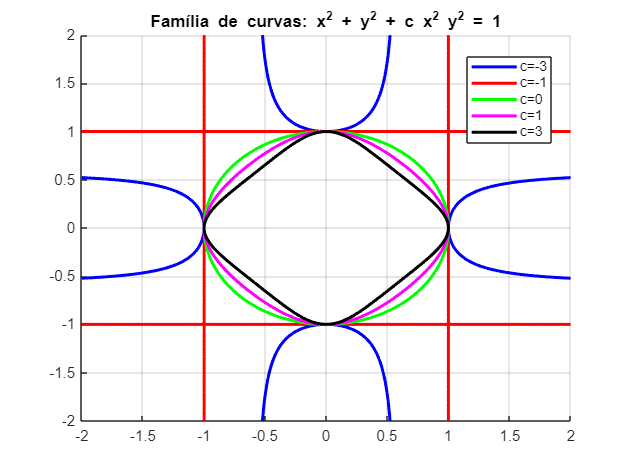

% Define os valores de c (pode incluir outros inteiros conforme desejar)
c_values = [-3, -1, 0, 1, 3];

% Define um vetor de cores para diferenciar as curvas
colors = ['b', 'r', 'g', 'm', 'k'];

% Cria uma nova figura e mantém os gráficos na mesma janela
figure;
hold on;

% Loop para plotar cada membro da família de curvas
for i = 1:length(c_values)
    c = c_values(i);
    % Define a função implícita para o valor atual de c:
    % f(x,y) = x^2 + y^2 + c*x^2*y^2 - 1 = 0.
    f = @(x,y) x.^2 + y.^2 + c.*(x.^2.*y.^2) - 1;
    
    % Plota a curva utilizando fimplicit
    fimplicit(f, [-2, 2, -2, 2], colors(i), 'LineWidth', 2)
end

% Configurações finais do gráfico
grid on;
legend('c=-3', 'c=-1', 'c=0', 'c=1', 'c=3', 'Location', 'best')
title('Família de curvas: x^2 + y^2 + c x^2 y^2 = 1')
hold off;